# Monster Task Mision Control

session_filename = "" + ".txt";

1: Press the Reset Button on the Main Arduino

2: Attach MATLAB to your arduino

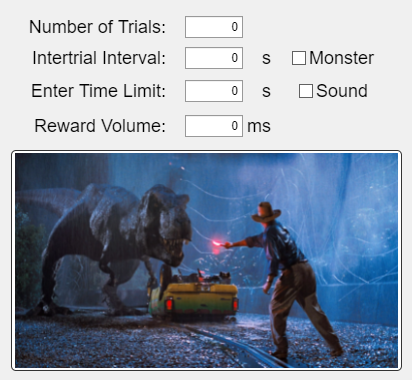

 

clear
clc
app = monsterapp;

arduino_handle = app.arduino_Obj;


3: Save serial input buffer to datalog.txt

 
%Wait until all bytes from the serial input buffer are accounted for
while(1)
    check1 = arduino_handle.NumBytesAvailable;
    pause(5);
    check2 = arduino_handle.NumBytesAvailable;
    if(check1==check2)
        break;
    end
end

serial_record = read(arduino_handle,arduino_handle.NumBytesAvailable,"string");
writelines(serial_record, "datalog.txt");

4: Extract data line by line and populate trial variables with data

 

fid = fopen("datalog.txt");
current_line = convertCharsToStrings(fgetl(fid));

type datalog.txt

# Trial has ended
Trial = 1
trial_duration = 17418
latency_to_enter = 10565
latency_to_trigger = 13141
latency_to_lick = 13163
escape_duration = 4233
mouse_entered = 1
threat_triggered = 1
port_licked = 1
# Trial has ended
Trial = 2
trial_duration = 10818
latency_to_enter = 5153
latency_to_trigger = 7149
latency_to_lick = 7170
escape_duration = 3627
mouse_entered = 1
threat_triggered = 1
port_licked = 1
# Trial has ended
Trial = 3
trial_duration = 8715
latency_to_enter = 3973
latency_to_trigger = 5912
latency_to_lick = 5934
escape_duration = 2759
mouse_entered = 1
threat_triggered = 1
port_licked = 1
# Trial has ended
Trial = 4
trial_duration = 10856
latency_to_enter = 3799
latency_to_trigger = 5547
latency_to_lick = 5569
escape_duration = 5265
mouse_entered = 1
threat_triggered = 1
port_licked = 1
# Trial has ended
Trial = 5
trial_duration = 9695
latency_to_enter = 4718
latency_to_trigger = 6690
latency_to_lick = 6711
escape_duration = 2962
mouse_entered = 1
threat_triggered = 1
port_


% Initialize current_trial
current_trial = 0;

% Initialize trial variables
trial_duration_var = zeros(10,2);
latency_to_enter_var = zeros(10,2);
latency_to_trigger_var = zeros(10,2);
latency_to_lick_var = zeros(10,2);
escape_duration_var = zeros(10,2);
mouse_entered_var = zeros(10,2);
threat_triggered_var = zeros(10,2);
port_licked_var = zeros(10,2);

% Fill trial variables
while isstring(current_line)
    
    % increase current_trial
    if contains(current_line, "# Trial has ended")
        current_trial = current_trial + 1;
    end 
    
    % Fill trial_duration_var
    if contains(current_line, 'trial_duration = ')
        trial_duration_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line,'trial_duration = '))
             ];
    end

    % Fill latency_to_enter_var
    if contains(current_line, 'latency_to_enter = ')
        latency_to_enter_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'latency_to_enter = '))
            ];
    end

    % Fill latency_to_trigger_var
    if contains(current_line, 'latency_to_trigger = ')
        latency_to_trigger_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'latency_to_trigger = '))
            ];
    end    

    % Fill latency_to_lick_var
    if contains(current_line, 'latency_to_lick = ')
        latency_to_lick_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'latency_to_lick = '))
            ];
    end    

    % Fill escape_duration_var
    if contains(current_line, 'escape_duration = ')
        escape_duration_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'escape_duration = '))
            ];
    end

    % Fill mouse_entered_var
    if contains(current_line, 'mouse_entered = ')
        mouse_entered_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'mouse_entered = '))
            ];
    end

    % Fill threat_triggered_var
    if contains(current_line, 'threat_triggered = ')
        threat_triggered_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'threat_triggered = '))
            ];
    end

    % Fill port_licked_var
    if contains(current_line, 'port_licked = ')
        port_licked_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'port_licked = '))
            ];
    end    

    %move to next line after checking through all the if statements
    current_line = convertCharsToStrings(fgetl(fid));

end

5: Create Data Table

 

trial_duration = trial_duration_var(:,2);
latency_to_enter = latency_to_enter_var(:,2);
latency_to_trigger = latency_to_trigger_var(:,2);
latency_to_lick = latency_to_lick_var(:,2);
escape_duration = escape_duration_var(:,2);
mouse_entered = mouse_entered_var(:,2);
threat_triggered = threat_triggered_var(:,2);
port_licked = port_licked_var(:,2);

session_data = table( ...
    trial_duration, ... 
    latency_to_enter, ...
    latency_to_trigger, ...
    latency_to_lick, ...
    escape_duration, ...
    mouse_entered, ...
    threat_triggered, ...
    port_licked ...
    )

session_data = 10×8 table
    trial_duration    latency_to_enter    latency_to_trigger    latency_to_lick    escape_duration    mouse_entered    threat_triggered    port_licked
    ______________    ________________    __________________    _______________    _______________    _____________    ________________    ___________

        17418              10565                13141                13163              4233                1                 1                 1     
        10818               5153                 7149                 7170              3627                1                 1                 1     
         8715               3973                 5912                 5934              2759     


writetable(session_data, session_filename);

Unrecognized function or variable 'session_filename'.


session_data